# Recurrent Neural Network for Speech Command Recognition

This example shows how to train a deep learning model for speech command recognition. 

The example uses the[ Speech Commands Dataset](https://ssd.mathworks.com/supportfiles/audio/google_speech.zip) to train a Long Short-Term Memory Network to recognize a given set of commands.

This example used *Audio Toolbox*™. 

clear; clc;
rng('default');

## Download dataset

This example uses the [Google Speech Commands Dataset](https://ai.googleblog.com/2017/08/launching-speech-commands-dataset.html).  

Use *download_data.mlx* script to download the dataset. 

The Speech Commands Dataset has 65,000 one-second long utterances of 30 short words, by thousands of different people.

dataFolder = 'google_speech';

## Load dataset

Audio data is loaded as an audio datastore using [audioDatastore](https://it.mathworks.com/help/audio/ref/audiodatastore.html) function that creates an audioDatastore object. 

Since train, validation, and test division is provided, three audioDatastore objects are created. 

`ads_train`, `ads_val` and `ads_test` are audioDatastore objects that manage a collection of audio files. An  audioDatastore object  acts as a reference (or a pointer)  to a data source, such as a folder of audio files. When creating an audioDatastore`,`basic meta information about the data are stored, such as file names and the formats. The dataset is not imported, but files are imported when needed (e.g. during the training).

If `IncludeSubfolders` is set to true, the subfolder are included. Since each subfolder contains audio files of the same class, `LabelSource` is set to `foldernames`.

ads_train = audioDatastore(fullfile(dataFolder, 'train'), ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');



ads_val = audioDatastore(fullfile(dataFolder, 'validation'), ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');


ads_test = audioDatastore(fullfile(dataFolder, 'test'), ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

The different labels are displayed

disp(unique(ads_train.Labels))

## **Choose Words to Recognize**

includeFraction = 0.05; %fraction of unknown words to consider
commands = categorical(["left","right","on","off","stop","go", "yes","no"]);

`commands` specifies the words that you want your model to recognize as commands. A subset of the words included in the dataset is used. 

All worlds that are not commands are labelled as `unknown. `The network will use the group of `unknown `words to learn the difference between commands and all other words. 

To reduce the class imbalance between the known and unknown words and speed up processing, a fraction of the unknown words in the training set is included. More in detail, the 5% of the unknown words are retained. 

 [`subset`](https://it.mathworks.com/help/audio/ref/audiodatastore.subset.html) is used to create a datastore that contains only the commands and the subset of unknown words. 

 The number of examples belonging to each category is computed using [countEachLabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.counteachlabel.html?searchHighlight=countEachLabel&s_tid=srchtitle) function. 

The word selection step is performed on train, validation, and test sets. 

% prepare train set
isCommand = ismember(ads_train.Labels,commands);
isUnknown = ~isCommand;

mask_train = rand(numel(ads_train.Labels),1) < includeFraction;
isUnknown = isUnknown & mask_train;
ads_train.Labels(isUnknown) = categorical("unknown");

ads_train = subset(ads_train,isCommand|isUnknown);
countEachLabel(ads_train)

% prepare validation set
isCommand = ismember(ads_val.Labels,commands);
isUnknown = ~isCommand;


mask_val = rand(numel(ads_val.Labels),1) < includeFraction;
isUnknown = isUnknown & mask_val;
ads_val.Labels(isUnknown) = categorical("unknown");

ads_val = subset(ads_val,isCommand|isUnknown);
countEachLabel(ads_val)

% prepare test set
isCommand = ismember(ads_test.Labels,commands);
isUnknown = ~isCommand;

mask_test = rand(numel(ads_test.Labels),1) < includeFraction;
isUnknown = isUnknown & mask_test;
ads_test.Labels(isUnknown) = categorical("unknown");

ads_test = subset(ads_test,isCommand|isUnknown);
countEachLabel(ads_test)

## Visualize data

In this section some waveforms are shown.

The audio file is read with [audioread](https://it.mathworks.com/help/matlab/ref/audioread.html) function. The audio data in the file is returned as an m-by-n matrix, where m is the number of audio samples read and `n` is the number of audio channels in the file.

The function audioread also returns the sample rate, in hertz, of the audio data that is 16000 for this dataset.

The function [sound](https://it.mathworks.com/help/matlab/ref/sound.html) converts the matrix of signal data to sound.

idx = randperm(numel(ads_train.Files),3);
for i = 1:3
    [x,fs] = audioread(ads_train.Files{idx(i)});
    subplot(1,3,i)
    plot(x)
    title(string(ads_train.Labels(idx(i))))
    
    sound(x,fs)
    pause(2)
end

## Features Extraction

The function [transform](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html?searchHighlight=transform&s_tid=srchtitle#responsive_offcanvas) transforms the input datastore using the transformation function `featuresExtraction, `defined at the bottom of the live script in Helper function section.  It returns the transformed datastore.

The function `featuresExtraction `is used to extract features from the audio files. 

More in detail, **Mel frequency cepstrum coefficients (MFCC)** are popular features extracted from speech signals for recognition tasks.

In the source-filter model of speech, cepstral coefficients are understood to represent the filter (vocal tract). The vocal tract frequency response is relatively smooth, whereas the source of voiced speech can be modeled as an impulse train. As a result, the vocal tract can be estimated by the spectral envelope of a speech segment.

The motivating idea of Mel  frequency cepstral coefficients is to compress information about the vocal tract (smoothed spectrum) into a small number of coefficients based on an understanding of the cochlea. Although there is no hard standard for calculating the coefficients, the basic steps are outlined by the diagram.

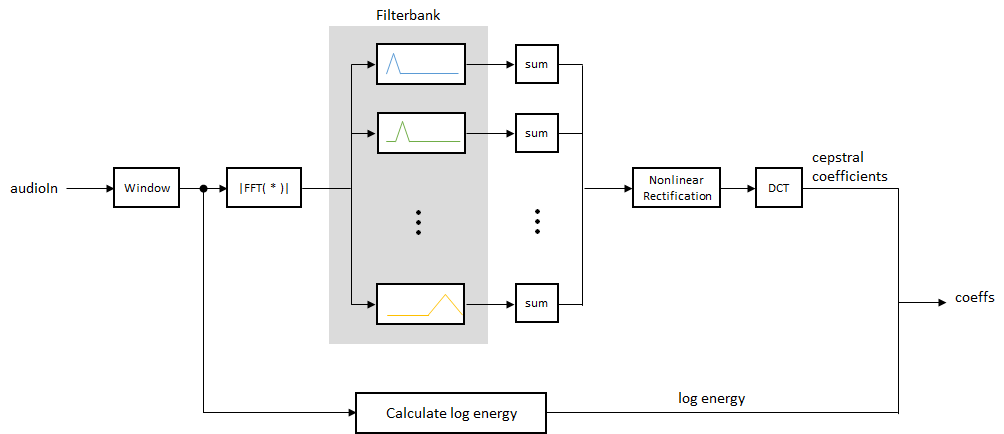

The function [mfcc](https://it.mathworks.com/help/audio/ref/mfcc.html#mw_42368d66-4f36-4220-a679-1ab088533c79) extracts  MFCC from input audio signal, returned as an  *L*-by-*M* matrix, where:

- L is the number of analysis windows the audio signal is partitioned into (14 in this example)

- M is the number of coefficients returned per frame

ads_trainTr = transform(ads_train,@featuresExtraction);
ads_valTr = transform(ads_val,@featuresExtraction);
ads_testTr = transform(ads_test,@featuresExtraction);

Data is read from `ads_trainTr. `It is a cell array containing a 14-by-M matrix. 

disp(read(ads_trainTr))

## Create test validation and test sets

The function [readall](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.readall.html) reads all data in datastore. The aim is to read all data from datastore transformed in the previous section for further manipulation.

The function [removecats](https://it.mathworks.com/help/matlab/ref/categorical.removecats.html) is used to remove empty categories from the categorical array representing the labels. 

Data extraction takes some minutes to execute. If `doExtraction` is set to `false`, the files *TRAIN.mat*, *VAL.mat* and *TEST.mat* are loaded. 

doExtraction = false;

if doExtraction
    Train = readall(ads_trainTr);
    YTrain = removecats(ads_train.Labels);
    TRAIN.x = Train;
    TRAIN.y = YTrain;
    
    Val = readall(ads_valTr);
    YVal = removecats(ads_val.Labels);
    VAL.x = Val;
    VAL.y = YVal;
    
    Test = readall(ads_testTr);
    Ytest = removecats(ads_test.Labels);
    TEST.x = Test;
    TEST.y = Ytest;
    
    save('TRAIN.mat', '-struct', 'TRAIN');
    save('VAL.mat', '-struct', 'VAL');
    save('TEST.mat', '-struct', 'TEST');
    
    
else
    TRAIN = load('TRAIN.mat');
    VAL = load('VAL.mat');
    TEST =  load('TEST.mat');
    
    Train = TRAIN.x;
    YTrain = TRAIN.y;
    
    Val = VAL.x;
    YVal= VAL.y;
    
    Test= TEST.x;
    Ytest= TEST.y;
end


## Number of returned coefficients

In this section, the histogram of number of return coefficients is shown. Most of the data have 98 returned coefficients.

func = @(x) size(x,2);

L = cellfun(func,Train);
figure;
h = histogram(L);
title('Number of returned coefficients')
xlabel('Number')
ylabel('Count')

## Class distribution

The distribution of the different class labels in the training, validation and test sets is shown

subplot(3,1,1)
histogram(YTrain)
title("Training Label Distribution")
subplot(3,1,2)
histogram(YVal)
title("Validation Label Distribution")
subplot(3,1,3)
histogram(YVal)
title("Test Label Distribution")

## LSTM Network definition

LSTM networks can learn long-term dependencies between time steps of sequence data.  This example uses the bidirectional LSTM layer [bilstmLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html), as it looks at the sequence in both forward and backward directions.

Because each input is a 14-by-M matrix (see for example variable `Train`) , the input size is set to 14. The input layer is a  [sequenceInputLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.sequenceinputlayer.html)  that inputs sequence data to the network and specifies the number of features that is this example is 14. 

Network consists of two stacked bidirectional LSTM layers with 32 hidden units. The first [bilstmLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html) outputs the complete sequence since `OutputMode` is set to `sequence. `The second  [bilstmLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html) outputs the last time step of the sequence (`OutputMode `is set to `last`)`. `This command instructs the bidirectional LSTM layer to map the input time series into 32 features and then prepares the output for the [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) of size `numClasses. `

The [`softmaxLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html) activation function normalizes the output of the last [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) . The output of the softmax layer consists of positive numbers that sum to one, which can then be used as classification probabilities by the classification layer.

The final layer is the [`classificationLayer`](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html). This layer uses the probabilities returned by the softmax activation function for each input to assign the input to one of the mutually exclusive classes and compute the loss. 

inputSize = 14;
numHiddenUnits = 32;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits, 'OutputMode',"sequence")
    bilstmLayer(numHiddenUnits, 'OutputMode',"last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

## Train Network

In this section the [training options](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html) (hyperparameter) are set:

- `maxEpochs` is the number of training  epochs. An epoch is a full training cycle on the entire training data set.

- `miniBatchSize` is the size of the batch of data used during network training. The batch size is a hyperparameter that defines the number of instances to work through before updating the internal model parameters. For each training epoch, the train set is divided into batches of size 64. 

- `IterForEpoch` specifies the frequency of the validation and the frequency of verbose printing. The validation data is not used to update the network weights. 

- The network is trained using `Adam` optimizer with an initial learning rate of 0.01

- To pad the data to have the same length as the longest sequences, `SequenceLength` is specified as `'longest'`

- Because LSTM layers process sequence data one time step at a time, when the layer `OutputMode` property is `'last'`, any padding in the final time steps can negatively influence the layer output. To pad or truncate sequence data on the left, set the [`'SequencePaddingDirection'`](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html#bu59f0q_sep_mw_510bf059-b226-4d7d-9888-7b78b668bde0) option to `'left'`.

The function [trainNetwork](https://it.mathworks.com/help/deeplearning/ref/trainnetwork.html) trains the network specified by `layers` for the speech command recognition task using the data and labels in the cell array `Train` and YTrain and the training options defined by `options_lstm`. By default, [trainNetwork](https://it.mathworks.com/help/deeplearning/ref/trainnetwork.html) uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. It is possible to specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

For a classification task, the loss is the cross-entropy loss. The accuracy is the percentage of images that the network classifies correctly.

Training requires about 10 minutes to execute. If `dotraining `is set to `true`, the trained network is then saved in 'lstm_net.mat' file, using the  [save](https://it.mathworks.com/help/matlab/ref/save.html) function, otherwise a pre-trained network is loaded. 

.

maxEpochs = 30;
miniBatchSize = 64;
IterForEpoch = floor(numel(YTrain) / miniBatchSize);

options_lstm = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData', {Val,YVal}, ...
    'ValidationFrequency', IterForEpoch, ...
    'VerboseFrequency',IterForEpoch,...
    'Shuffle','every-epoch', ...
    'SequenceLength', 'longest', ...
    'SequencePaddingDirection', 'left',...
    'Plots','training-progress');

doTraining = false;
if doTraining
    net_lstm = trainNetwork(Train,  YTrain,  layers,options_lstm);
    save('lstm_net.mat', 'net_lstm');
else
    net_lstm = load('lstm_net.mat');
    net_lstm = net_lstm.net_lstm;
end

## Performance evaluation

The performance of the network is evaluated on test set. Predictions are computed with [classify](https://it.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) function. 

The function  [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html) creates the confusion matrix chart for the speech command recognition  task.

if `cm.RowSummary` is specified ad 'row-normalized' the true positive rates and false positive rates are shown for each label. 

pred = classify(net_lstm, Test);
figure
accuracy = sum(pred == Ytest)/numel(Ytest);
disp(['Accuracy on test set: ' num2str(accuracy)]);
cm = confusionchart(Ytest,pred);
cm.RowSummary = 'row-normalized';

## Further Practice

- Try to change the architecture of the neural network. Use Deep Network Designer App (DND) that provides a graphical interface for designing a neural network.

To open the DND app go to the **Apps** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html)

## Further readings

-  [audioDatastore](https://it.mathworks.com/help/audio/ref/audiodatastore.html)

-  [countEachLabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.counteachlabel.html?searchHighlight=countEachLabel&s_tid=srchtitle)

- [`subset`](https://it.mathworks.com/help/audio/ref/audiodatastore.subset.html) 

- [audioread](https://it.mathworks.com/help/matlab/ref/audioread.html)  

- [sound](https://it.mathworks.com/help/matlab/ref/sound.html) 

- [transform](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html?searchHighlight=transform&s_tid=srchtitle#responsive_offcanvas) 

- [removecats](https://it.mathworks.com/help/matlab/ref/categorical.removecats.html)  

- [readall](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.readall.html)  

- [mfcc](https://it.mathworks.com/help/audio/ref/mfcc.html#mw_42368d66-4f36-4220-a679-1ab088533c79) 

- [sequenceInputLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.sequenceinputlayer.html)  

- [bilstmLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.bilstmlayer.html)  

- [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html)

- [`classificationLayer`](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html) 

- [`softmaxLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html) 

- [training options](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html) 

- [`'SequencePaddingDirection'`](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html#bu59f0q_sep_mw_510bf059-b226-4d7d-9888-7b78b668bde0) 

- [trainNetwork](https://it.mathworks.com/help/deeplearning/ref/trainnetwork.html)  

- [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html)  

- [classify](https://it.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html)

## Helper function

function dataOut = featuresExtraction(dataIn)
fs = 16e3;
% coeffs = mfcc(x,fs);
dataOut = {mfcc(dataIn,fs)'};
end
